# **IO424 - Synchro Measurement**

This example shows how to set up the IO424 module for Synchro measurements. The Synchro signal is generated by the IO107 analog output module. The signal can however be generated in other ways, for example, using Synchro generators or an actual Synchro transformer.

The IO424 is a 4-channel, 16-bit, LVDT/RVDT/Resolver/Synchro converter I/O module. This module only has read capabilities, but can generate the excitation reference signal for Resolver and LVDT/RVDT (Linear Variable Differential Transformers/Rotary Variable Differential Transformers).

## Setup

### Prerequisites

You will require at least the following to run this example:

- Speedgoat real-time target machine with one IO424 I/O module **(RS variant)** installed

- Connector cable (50-pin MDR) from the IO424 module to the terminal board

- 50-pin MDR terminal board with jumper wires

Optional:

- One [IO107 I/O module](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io107) installed

- Connector cable (68-pin SCSI) from the IO107 module to the terminal board

- 68-pin SCSI terminal board with jumper wires

### What is a Synchro?

Synchros are rotary transformers designed to measure angular position. They consist of a primary winding mounted on the rotor and three secondary windings mounted on the stator, oriented 120 degrees apart. An excitation sinusoidal waveform is applied to the primary winding. The rotor's angular position is then determined by analyzing the amplitude and phase relationships of the signals induced in the three secondary windings.

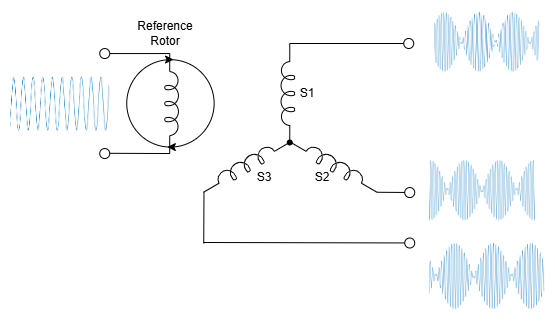

### Test Setup

Because the IO424 is designed for signal measurement, the Synchro excitation signal must be provided by an external source. In this example, the IO107 module is used, leveraging its DMA capability to achieve higher sampling rates. 

The IO107 is a module with differential analog outputs. The S1, S2, and S3 inputs of the IO424 are single-ended analog inputs. Consequently, only the positive Out+ pin is connected, and the reference is given with the Output Return pin.

There is no single-ended configuration in the IO107 blockset, so the module will always be differential, and for this reason, when using only one pin, the resulting amplitude is half the amplitude defined in the model.

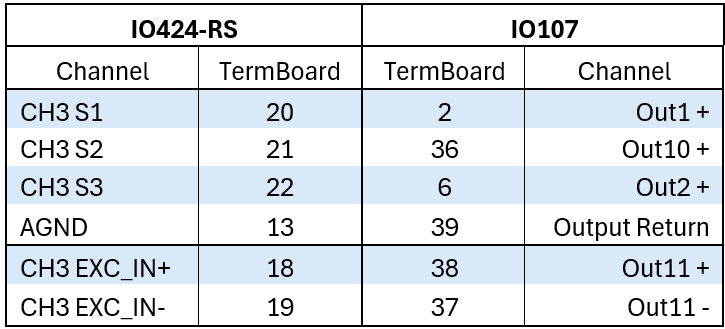

The full pin mapping of the IO424 can be found here: [IO424 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io424_pin_mapping)

## Model Description

### Synchro Signal Generation

The model's signal generation section, located on the left, uses four [Sine Wave](https://mathworks.com/help/dsp/ref/sinewave.html) blocks from the [DSP System Toolbox](https://www.mathworks.com/help/dsp/index.html) to create sampled sinusoidal signals. Each block generates a frame of 450 elements, enabling the IO107's Direct Memory Access (DMA) capability for high-speed signal output. One Sine Wave block generates a 6.5 VRMS, 1 kHz reference signal. This reference signal is then modulated by three lower-frequency (10 Hz) sinusoidal signals: three cosine waves with a phase difference of 120° between them (S1, S2, S3), which serve as the modulating signals. Since the S1, S2, and S3 inputs of the IO424 are single ended, and the outputs of the IO107 are differential (the modulating signal has an amplitude of 1), the resulting S1, S2, and S3 inputs will be half the reference amplitude in the physical layer.

If no Speedgoat analog output module is available, alternative signal generation methods can be employed. This includes using external signal generators or a separate Simulink model containing continuous Sine Wave generators. The latter allows for signal data extrapolation, which can be used to generate CSV files for external signal generators. In a real-world application, an actual Synchro sensor would be used as the signal source.

### Synchro Signal Reading

The right side of the model implements the Synchro signal acquisition and processing. In the[ IO424 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io424_setup) block, the input range is configured to optimally match the generated signal levels. The [IO424 Synchro Read](https://www.speedgoat.com/help/slrt/page/refentry_io424_synchro_read) block is used for Position and Status reading. Status readings are enabled, and the Position conversion is set to radians. Each channel, in this case a single channel, provides two output ports: Position, and Status. The Position ports each output a single numerical value, while the Status port outputs a five-element vector, where each element corresponds to a specific error bit. For diagnostic purposes, the status bits are extracted with a [Demux block](https://mathworks.com/help/simulink/slref/demux.html), to access individual error bits.

## Open Simulink Model

 
modelName = 'sgMdl_IO424_SynchroMeasurementTest';
open_system(modelName);         % Open Simulink model

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

The figure below shows the generated signals for the first turn of the simulated Synchro.

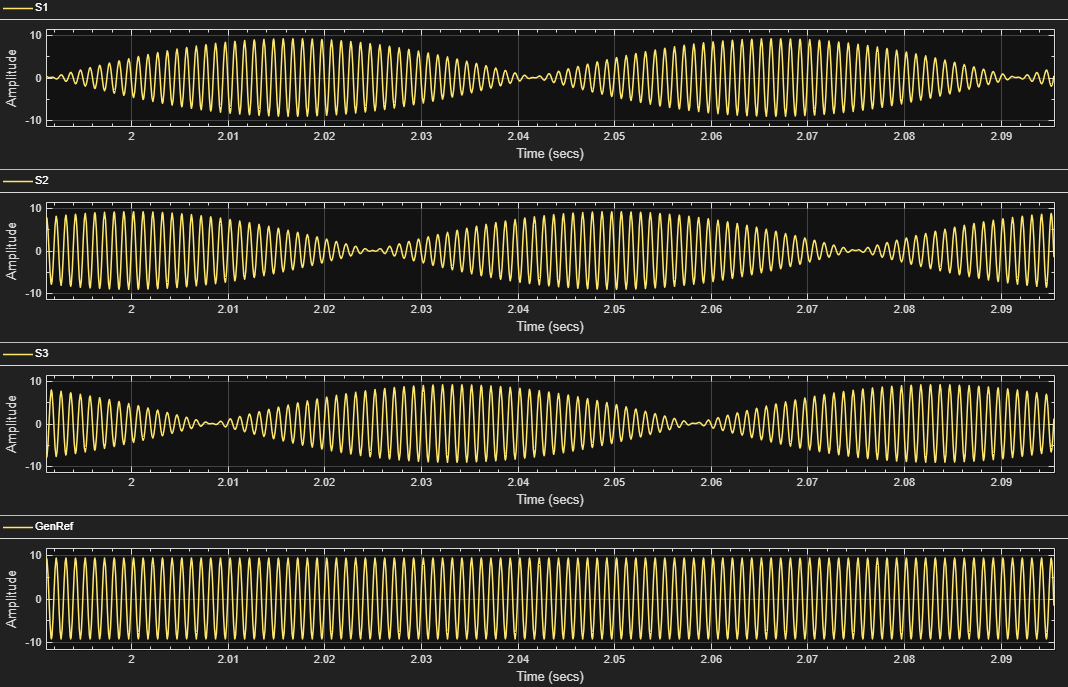

The readings align with what was configured in the Synchro signal generation. The position steadily goes from 0 rad to 2$\pi$ rad in a sawtooth wave with a period of 100 ms, so 10 Hz. No errors were introduced in this example, so all the status bits stay at zero. The Time x-axis is in seconds.

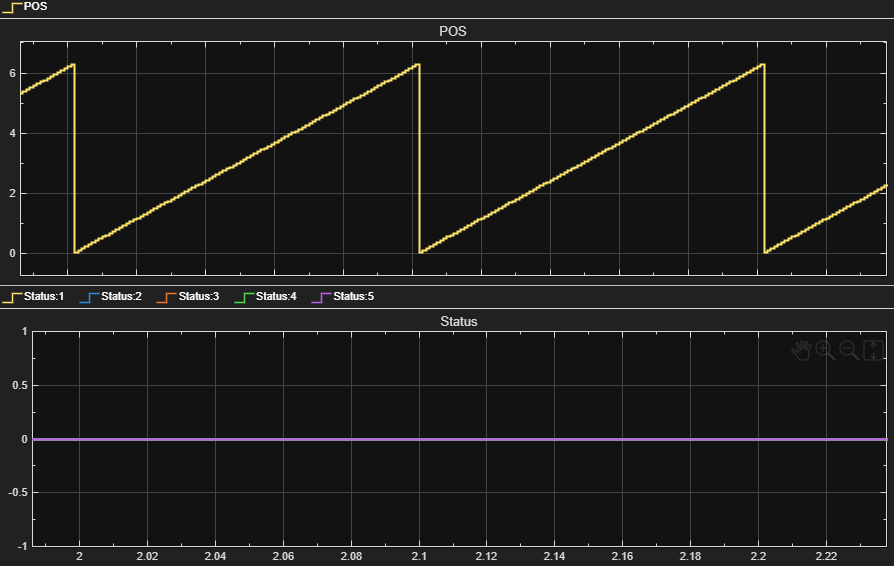

## Additional References

- [IO424 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io424)